Variables independientes $\theta_1 ,\theta_2 ,\;X_a ,\;Z_a$

clear
clc

b=2.365; %Longitud total en Y
h=0.57; %Longitud total en X
n=100;
xi=linspace(-0.5*h,0.5*h,n);
yi=linspace(-0.5*b,0.5*b,n);
[X,Y] = meshgrid(xi,yi);
Z = zeros(size(X));

%Coordenadas del punto Pi respecto al punto medio del plano (origen)

Pix=h/2; 
Piy=b/2;
Piz=0.4;


Pi=[Pix Piy Piz]

Pi =     0.2850    1.1825    0.4000



beta=15; %Balanceo
theta=0; %Cabeceo
Xa=00; %Avance
Za=0; %Arfada


%Funciones en la parte final del código

Pf=Pos(Pi,theta,beta,Za,Xa,h,b) %vector normal

Pf =     0.2850    1.0387    0.6924



pf2=PosFinal(Pi,theta,beta,Za,Xa) % Todo por componentes

pf2 =     0.2850    1.0387    0.6924



pf3=PosFinal2(Pi,theta,beta,Za,Xa) % Matriz de transformación

pf3 =     1.0000         0         0    0.2850
         0    0.9659   -0.2588    1.0387
         0    0.2588    0.9659    0.6924
         0         0         0    1.0000


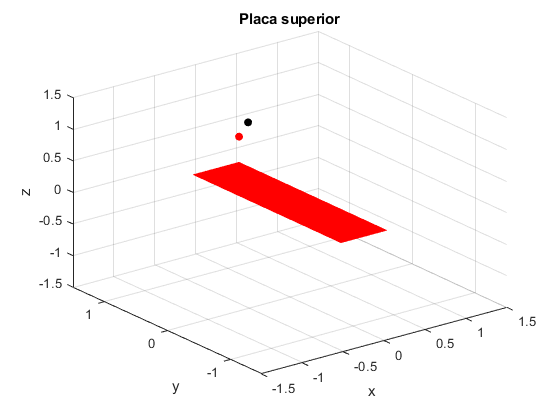

%Las coordenadas son la última columna, primeras 3 filas; X, Y y Z
%respectivamente

scatter3(Pix,Piy,Piz,'filled','r') %Punto inicial en rojo
hold on
scatter3(Pf(1),Pf(2),Pf(3),'filled','k')%Pf en rojo, vector normal
%scatter3(pf2(1),pf2(2),pf2(3),'filled','b')%Pf en azul, método de vistas laterales
%scatter3(pf3(1,4),pf3(2,4),pf3(3,4),'filled','y')%Pf en amarillo, matriz de transformación
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
hold off
xlim([-1.5 1.5])
ylim([-1.5 1.5])
zlim([-1.5 1.5])
xlabel("x")
ylabel("y")
zlabel("z")
title("Placa superior")

## Movimientos para el punto Pi

PfBalanceo=ones([31 3]);
PfCabeceo=ones([37 3]);
PfAvance=ones([51 3]);
PfArfada=ones([51 3]);

for i=1:31
    PfBalanceo(i,:)=Pos(Pi,0,i-16,0,0,h,b);
end

for i=1:37
    PfCabeceo(i,:)=Pos(Pi,i-19,0,0,0,h,b);
end

for i=1:51
    PfAvance(i,:)=Pos(Pi,0,0,0,(i-1)/51*0.3,h,b);
end

for i=1:51
    PfArfada(i,:)=Pos(Pi,0,0,(i-1)/51*0.1,0,h,b);
end


## Gráficas de movimiento

###     1. Balanceo

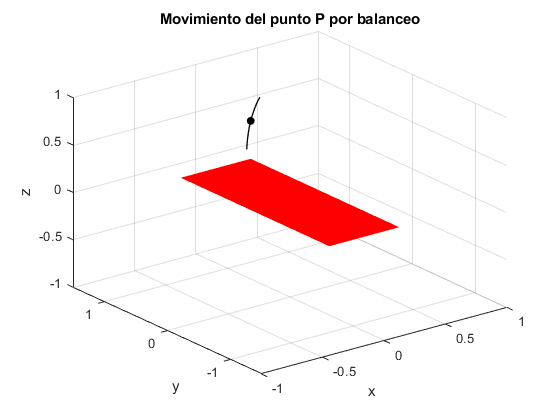

plot3(PfBalanceo(:,1),PfBalanceo(:,2),PfBalanceo(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por balanceo")

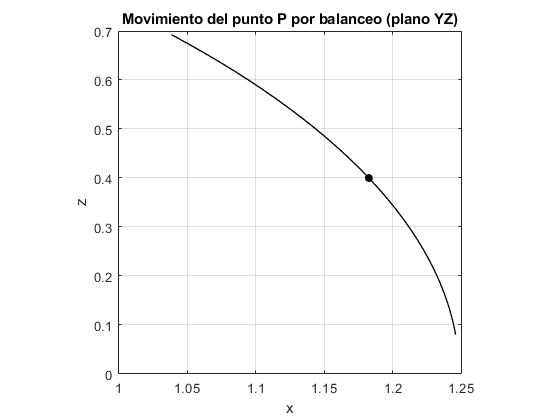

plot(PfBalanceo(:,2),PfBalanceo(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(2),Pi(3),'filled','k')
hold off
ylabel("z")
xlabel("x")
axis("square")
grid on
title("Movimiento del punto P por balanceo (plano YZ)")

###     2. Cabeceo

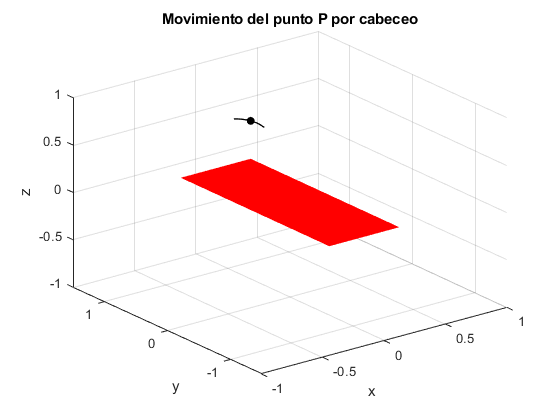

plot3(PfCabeceo(:,1),PfCabeceo(:,2),PfCabeceo(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por cabeceo")

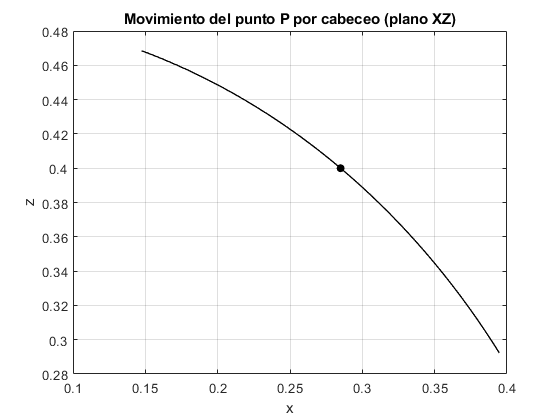


plot(PfCabeceo(:,1),PfCabeceo(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(1),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("z")
grid on
title("Movimiento del punto P por cabeceo (plano XZ)")

###     3. Avance

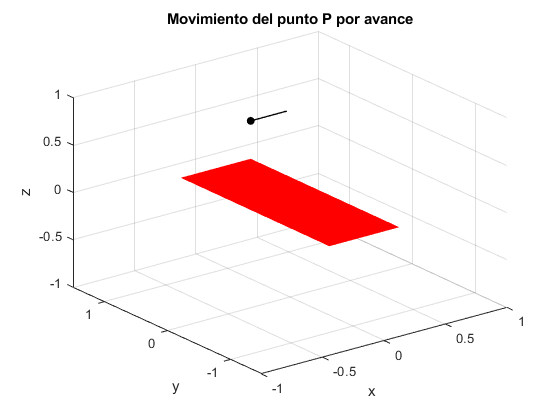

plot3(PfAvance(:,1),PfAvance(:,2),PfAvance(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por avance")

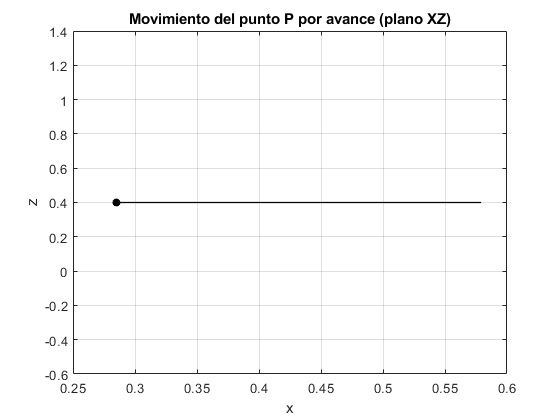

plot(PfAvance(:,1),PfAvance(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(1),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("z")
grid on
title("Movimiento del punto P por avance (plano XZ)")

###     4. Arfada

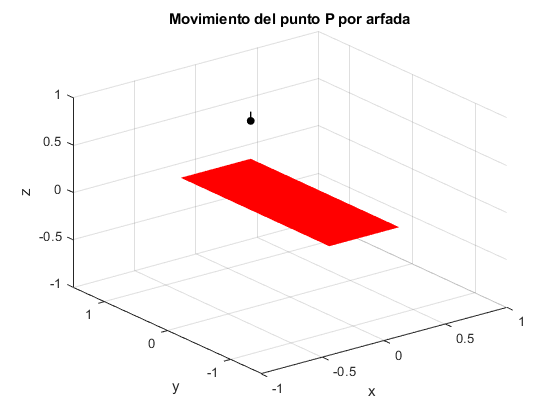

plot3(PfArfada(:,1),PfArfada(:,2),PfArfada(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por arfada")

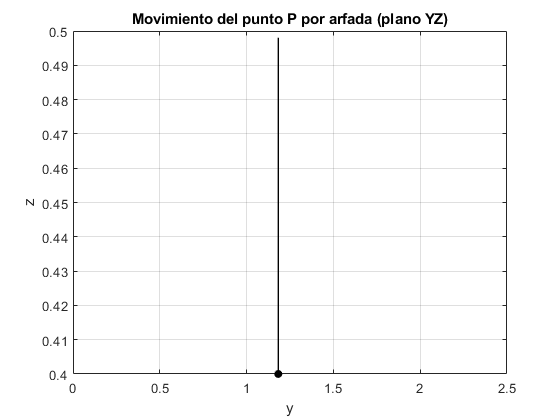

plot(PfArfada(:,2),PfArfada(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(2),Pi(3),'filled','k')
hold off
xlabel("y")
ylabel("z")
grid on
title("Movimiento del punto P por arfada (plano YZ)")

function [Pf] = Pos(Pi,theta,beta,Za,Xa,h,b) %Vector normal
Pfx=Pi(1).*cosd(theta)+Xa;
Pfy=Pi(2).*cosd(beta);
Pfz=-Pi(1).*sind(theta)+Pi(2).*sind(beta)+Za;
Pf=[Pfx Pfy Pfz]+Pi(3).*VectorNormal(h,b,theta,beta,Za,Xa);
end

function [N] = VectorNormal(h,b,theta,beta,Za,Xa)
P1=PosPlanoNormal([0 0 0],theta,beta,Za, Xa);
P2=PosPlanoNormal([0.5*h 0 0],theta,beta,Za, Xa);
P3=PosPlanoNormal([0 0.5*b 0],theta,beta,Za, Xa);
N=cross(P2-P1,P3-P1)./norm(cross(P2-P1,P3-P1));
end

function [Pf] = PosPlanoNormal(Pi,theta,beta,Za,Xa)
Pfx=Pi(1).*cosd(theta)+Xa;
Pfy=Pi(2).*cosd(beta);
Pfz=-Pi(1).*sind(theta)+Pi(2).*sind(beta)+Za;
Pf=[Pfx Pfy Pfz];
end

%Análisis de vistas laterales

function [Pf] = PosFinal(Pi,theta,beta,Za,Xa) 
Pfx=Pi(1).*(cosd(theta))+Pi(3).*sind(theta)+Xa;
Pfy=Pi(2).*cosd(beta)-Pi(3).*sind(beta);
Pfz=Za+Pi(3)-Pi(1).*sind(theta)+Pi(2).*sind(beta)-Pi(3).*(1-cosd(theta))-Pi(3).*(1-cosd(beta));
Pf=[Pfx Pfy Pfz];
end

%Matriz de transformación

function [Pf] = PosFinal2(Pi,theta,beta,Za,Xa) 
Pf=[1 0 0 Xa;0 1 0 0;0 0 1 Za;0 0 0 1]*[1 0 0 0;0 cosd(beta) -sind(beta) 0; 0 sind(beta) cosd(beta) 0; 0 0 0 1]*[cosd(theta) 0 sind(theta) 0;0 1 0 0; -sind(theta) 0 cosd(theta) 0;0 0 0 1]*[1 0 0 Pi(1);0 1 0 Pi(2);0 0 1 Pi(3);0 0 0 1];
end



